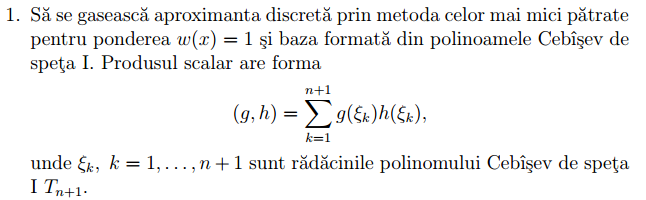

n = 10;
f = @(x) exp(x);

x = chebyshev_roots(n);
y = f(x);

base = chebyshev_I_base(n);
phi = base(x);

coeffs = phi \ y'

coeffs =     1.2661
    1.1303
    0.2715
    0.0443
    0.0055
    0.0005
    0.0000
    0.0000
    0.0000
    0.0000


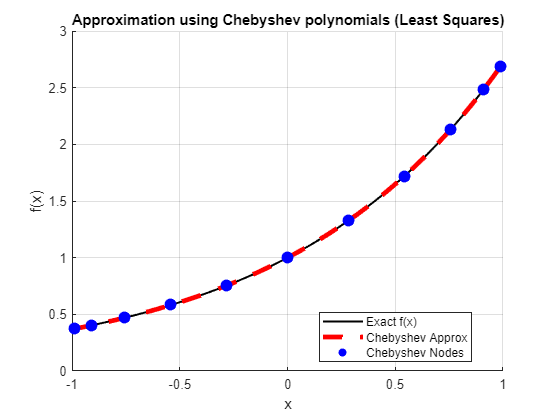


xx = linspace(-1, 1, 200);
approx = base(xx) * coeffs;

% Plotting real vs approximation
figure; 
hold on;
grid on;


% Exact function
plot(xx, f(xx), 'k-', 'LineWidth', 1.5, 'DisplayName', 'Exact f(x)');

% Approximated curve
plot(xx, approx, 'r--', 'LineWidth', 3.5, 'DisplayName', 'Chebyshev Approx');

% Chebyshev nodes
scatter(x, y, 80, 'bo', 'filled', 'DisplayName', 'Chebyshev Nodes');

legend("Location","best");

title('Approximation using Chebyshev polynomials (Least Squares)');
xlabel('x'); 
ylabel('f(x)');